# Week11: Satellite NPP

% safety first
close all
clear all

% read in the data
fn='NPP_VGPM_MODISR18_3x3_2003_2018.nc';
ncdisp(fn); % display data contents

Source:
           /Users/takamitsu3/Dropbox (GaTech)/Teaching/4305-PCOcean/2021/NPP_VGPM_MODISR18_3x3_2003_2018.nc
Format:
           netcdf4
Global Attributes:
           title        = 'Net Primary Production based on Standard VGPM of Behrenfeld and Falkowsky (1997) with MODIS R2018 satellite sensor. Original data is download from http://sites.science.oregonstate.edu/ocean.productivity/index.php'
           Conventions  = 'CF-1.6'
           CreationDate = '2021/11/03 12:45:06'
Dimensions:
           lon  = 120
           lat  = 60
           time = 192
Variables:
    lon 
           Size:       120x1
           Dimensions: lon
           Datatype:   double
           Attributes:
                       standard_name = 'lon'
                       long_name     = 'longitude'
                       units         = 'degrees_east'
                       _FillValue    = -99999
    lat 
           Size:       60x1
           Dimensions: lat
           Datatype:   double
           Attribu

lon=ncread(fn,'lon');
lat=ncread(fn,'lat');
time=ncread(fn,'time');
NPP=ncread(fn,'NPP');

**generate time average (long term mean) and make a global map quickly**[**¶**](http://localhost:8891/notebooks/4305-PCOcean/2021/week11_npp_exercise.ipynb#generate-time-average-(long-term-mean)-and-make-a-global-map-quickly)

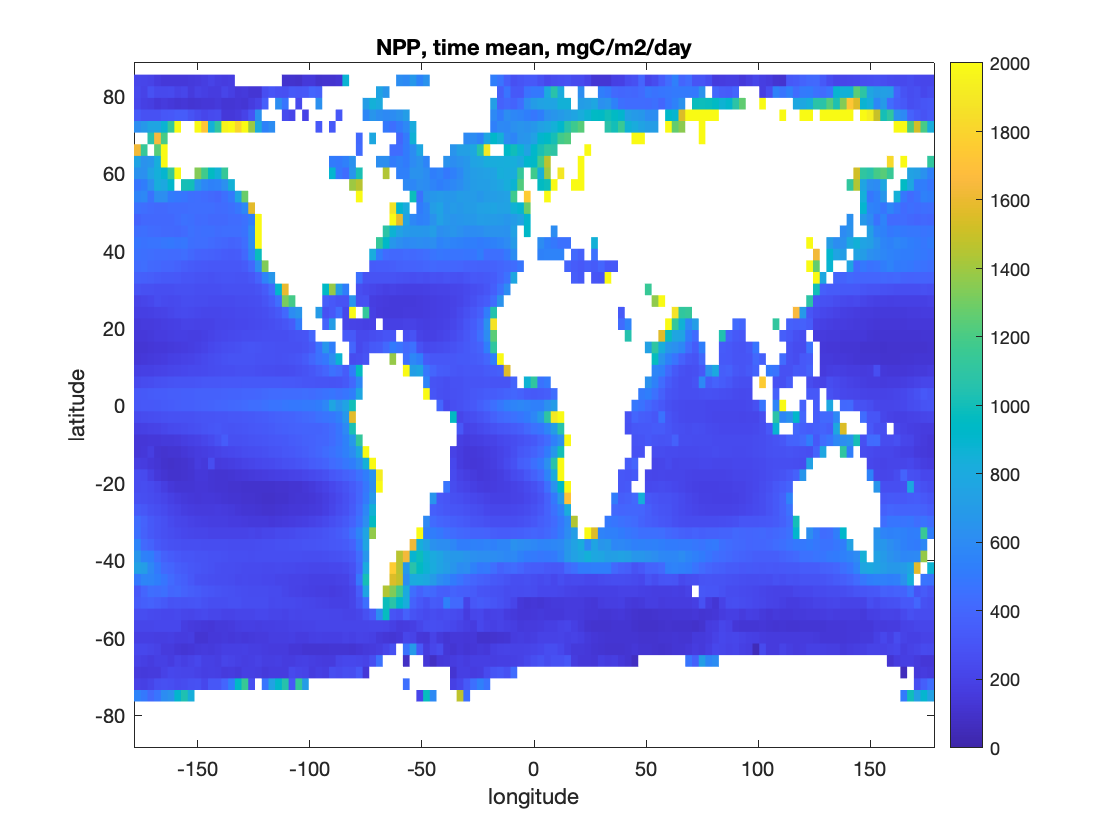

NPPave = nanmean(NPP,3);
figure(1);
pcolor(lon,lat,NPPave');
shading flat;
caxis([0,2000])
colorbar;
xlabel('longitude')
ylabel('latitude')
title('NPP, time mean, mgC/m2/day')

**select a specific location and draw time series**

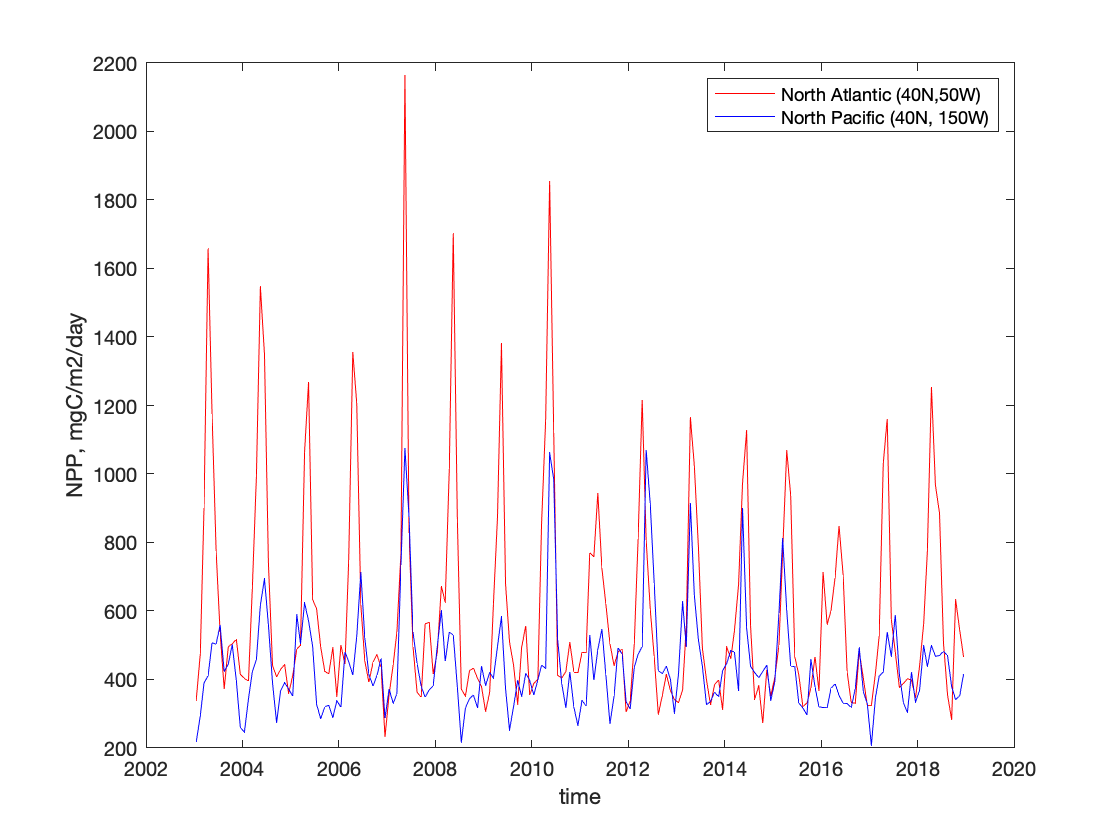

figure(2);
% North Atlantic, 40N, 50W
[dummy,Iy]=min(abs(lat-40));
[dummy,Ix]=min(abs(lon+50));
NPP_NA=squeeze(NPP(Ix,Iy,:));

% North Pacific, 40N, 150W
[dummy,Iy]=min(abs(lat-40));
[dummy,Ix]=min(abs(lon+150));
NPP_NP=squeeze(NPP(Ix,Iy,:));

dyear=time/365.25+2003;
plot(dyear,NPP_NA,'r-');
hold on;
plot(dyear,NPP_NP,'b-');
hold off;
legend({'North Atlantic (40N,50W)','North Pacific (40N, 150W)'});
xlabel('time')
ylabel('NPP, mgC/m2/day')

**select a specific month and draw NPP maps**

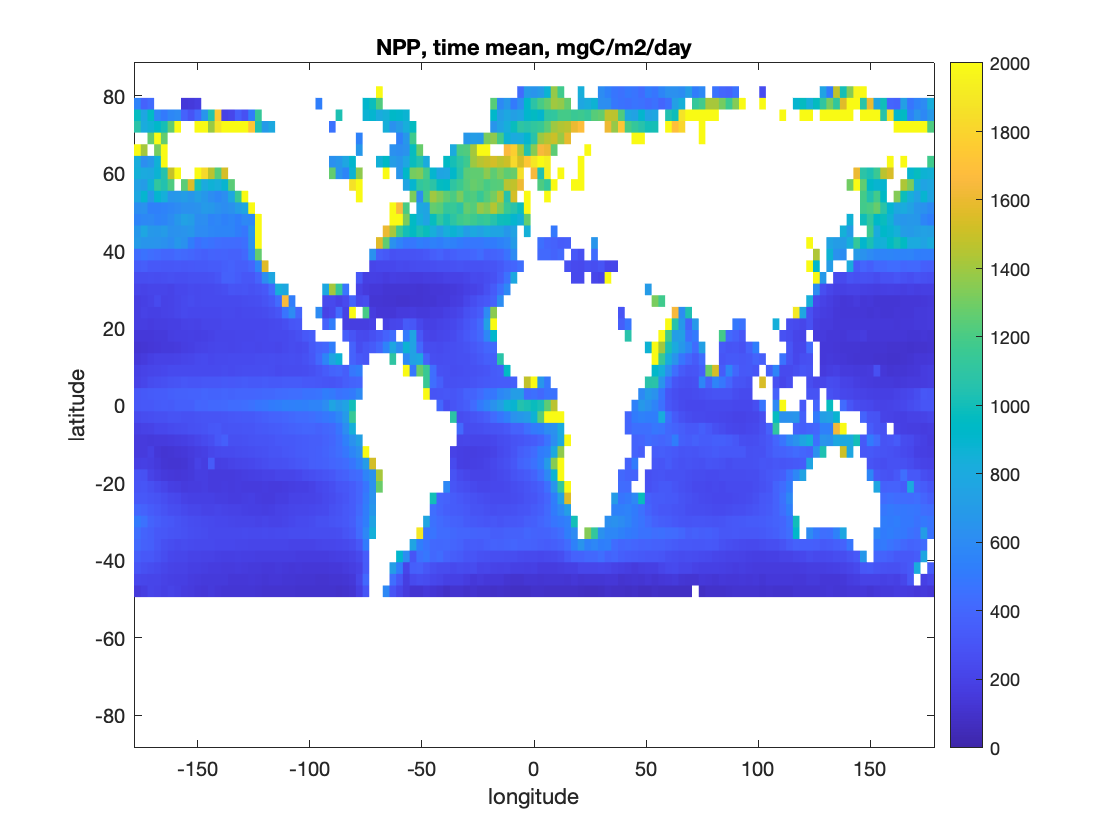

[Y,M,D]=datevec(time);
% select July
july = (M==7);
NPP_jul=nanmean(NPP(:,:,july),3);

figure(4);
pcolor(lon,lat,NPP_jul');
shading flat;
caxis([0,2000])
colorbar;
xlabel('longitude')
ylabel('latitude')
title('NPP, time mean, mgC/m2/day')

**Group the data by month and take averages for all years, then perform zonal mean (averaging all longitude), plot the result as a function of latitude for 4 months (Jan, Apr, Jul, Oct)**

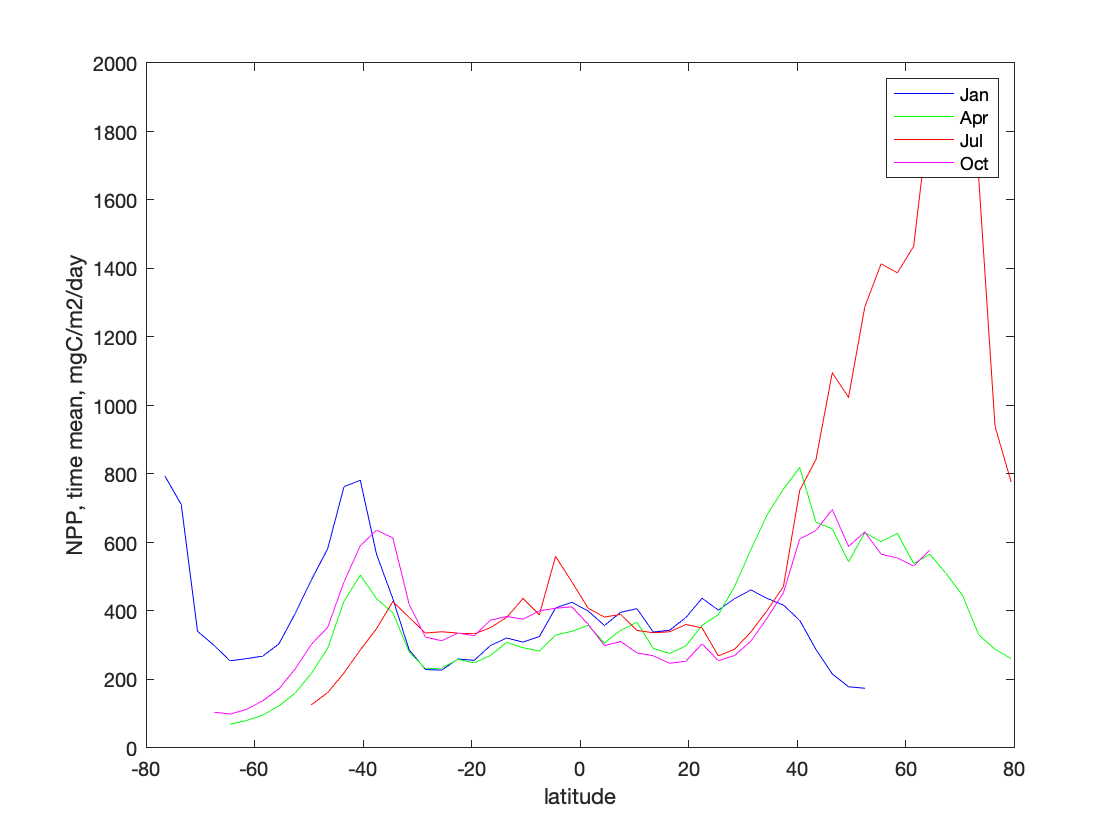

for m=1:12
    mon=(M==m);
    NPPc(:,:,m)=nanmean(NPP(:,:,mon),3);
end
NPPcx=squeeze(nanmean(NPPc,1));

figure(5);
plot(lat,NPPcx(:,1),'b-'); % Jan
hold on;
plot(lat,NPPcx(:,4),'g-'); % Apr
plot(lat,NPPcx(:,7),'r-'); % Jul
plot(lat,NPPcx(:,10),'m-'); % Oct
hold off;
legend({'Jan' 'Apr' 'Jul' 'Oct'});
xlabel('latitude')
ylabel('NPP, time mean, mgC/m2/day')